# **Simulation Pressure disturbution in a horizontal plug **

form** Zero to steady state** condition with **0.01 m,0.1 cm and 0.2 cm steps**

***Analytical,Implicit***, ***Explicit & Cranck Nicholson*** and compare them.

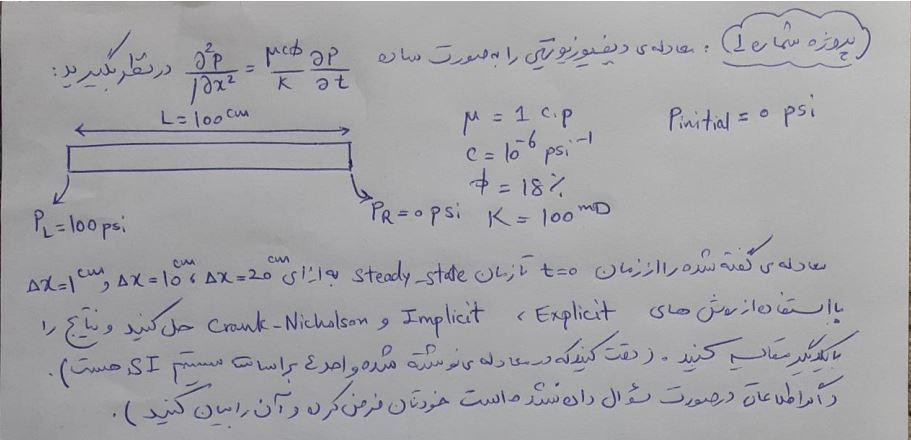

clc;clear;

# ** Asummption's Value**

#### **at the begining,we convert our initial data to SI system and because of that  calculated values all are in SI system.**

#### **Pressure from psi to Pa**

#### **viscosity from cp to Pa.s**

#### **Compressibility from psi^-1 to Pa^-1**

#### **Permeability from mD to M^2**

#### **length from cm to m**

#### in all types of calculation we set t=1 as our recommended time for reaching Steady-State condition(correction check passed in all conditions)

#### on the other hand,we run and save all of our methods in a variable with name "Ans" and after that we substitue it in some proper name values.

#### generally our answer format is a matrix that its rows indicates locations and columns show times.

Pi=0;   %pa
mu=1e-3;   %pa.s
Ct=1.45e-10;    %pa^-1
phi=0.18;   %fraction
k=9.869233000000002e-14;  %m^2
L=1;    %m
PL=689476; %pa
PR=0;   %pa

#### ***for Analytical solution we use equation below:***

#### 

#### the shrinking form exponential term is the key point in this method so we decided to set our time step equal to 1e-3 for increasing accuracy and also duo to better calculation process in this situation.

#### also,because of some issues ,we started time from our dt instead of 0

## ***Analytical solution***($\left.\Delta x=0\ldotp 01\;m\right)$

dt=1e-3;
tfinal=1;
dx=0.01;

Ans=zeros(L/dx,numel(dt:dt:tfinal));
Ans(:,1)=Pi; %assign initial pressure to all points
c=0;
for t=dt:dt:tfinal %time loop
    c=c+1;
    b=0;
    for j=(dx/2):dx:(1-dx/2)
        b=b+1;
        sigmaval=0;
        for n=1:100  %use a 100 value and ignore rest of the calculation after that
            sigmaval=sigmaval+(1/n)*exp((-(n^2)*(pi^2)/(L^2))*(k/(phi*mu*Ct))*t)*sin(n*pi*j/L);
        end
    w=(j/L+(2/pi)*sigmaval);
        Ans(b,c)=PL+(PR-PL)*w;
    end
end

AnsAnalytical1=Ans;


## ***Analytical solution***($\left.\Delta x=0\ldotp 1\;m\right)$

dt=1e-3;
tfinal=1;
dx=0.1;

Ans=zeros(L/dx,numel(dt:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
c=0;
for t=dt:dt:tfinal %time loop
    c=c+1;
    b=0;
    for j=(dx/2):dx:(L-dx/2)
        b=b+1;
        sigmaval=0;
        for n=1:100
            sigmaval=sigmaval+(1/n)*exp((-(n^2)*(pi^2)/(L^2))*(k/(phi*mu*Ct))*t)*sin(n*pi*j/L);
        end
    w=(j/L+(2/pi)*sigmaval);
        Ans(b,c)=PL+(PR-PL)*w;
    end
end

AnsAnalytical2=Ans;

## ***Analytical solution***($\left.\Delta x=0\ldotp 2\;m\right)$

dt=1e-3;
tfinal=1;
dx=0.2;

Ans=zeros(L/dx,numel(dt:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
c=0;
for t=dt:dt:tfinal %time loop
    c=c+1;
    b=0;
    for j=(dx/2):dx:(L-dx/2)
        b=b+1;
        sigmaval=0;
        for n=1:100
            sigmaval=sigmaval+(1/n)*exp((-(n^2)*(pi^2)/(L^2))*(k/(phi*mu*Ct))*t)*sin(n*pi*j/L);
        end
    w=(j/L+(2/pi)*sigmaval);
        Ans(b,c)=PL+(PR-PL)*w;
    end
end

AnsAnalytical3=Ans;

#### **for explicit condition we use Eq. below:**

#### 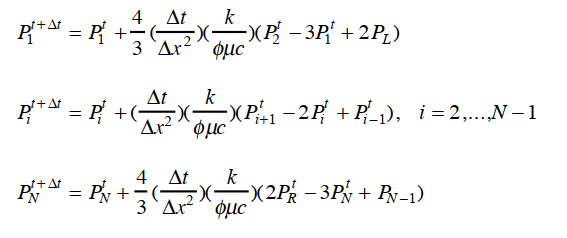

#### So we have three main line for first,mid and final points.

### ***Explicit***($\left.\Delta x=0\ldotp 01\;m\right)$

dt=1e-6;
tfinal=1;
dx=0.01;

Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
c=1;
for t=0:dt:tfinal  %time loop
    c=c+1;
    Ans(1,c)=Ans(1,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(2,c-1)-3*Ans(1,c-1)+2*PL);
    for j=2:(L/dx)-1
        Ans(j,c)=Ans(j,c-1)+((dt)/(dx^2))*((k)/(mu*Ct*phi))*(Ans(j+1,c-1)-2*Ans(j,c-1)+Ans(j-1,c-1));
    end
    Ans(L/dx,c)=Ans(L/dx,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(L/dx-1,c-1)-3*Ans(L/dx,c-1)+2*PR);
    
end
AnsExp1=Ans;

### ***Explicit***($\left.\Delta x=0\ldotp 1\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.1;
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
c=1;
for t=0:dt:tfinal %time loop
    c=c+1;
    Ans(1,c)=Ans(1,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(2,c-1)-3*Ans(1,c-1)+2*PL);
    for j=2:(L/dx)-1
        Ans(j,c)=Ans(j,c-1)+((dt)/(dx^2))*((k)/(mu*Ct*phi))*(Ans(j+1,c-1)-2*Ans(j,c-1)+Ans(j-1,c-1));
    end
    Ans(L/dx,c)=Ans(L/dx,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(L/dx-1,c-1)-3*Ans(L/dx,c-1)+2*PR);
    
end
AnsExp2=Ans;

### ***Explicit***($\left.\Delta x=0\ldotp 2\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.2;
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
c=1;
for t=0:dt:tfinal %time loop
    c=c+1;
    Ans(1,c)=Ans(1,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(2,c-1)-3*Ans(1,c-1)+2*PL);
    for j=2:(L/dx)-1
        Ans(j,c)=Ans(j,c-1)+((dt)/(dx^2))*((k)/(mu*Ct*phi))*(Ans(j+1,c-1)-2*Ans(j,c-1)+Ans(j-1,c-1));
    end
    Ans(L/dx,c)=Ans(L/dx,c-1)+(4/3)*((dt)/(dx^2))*(k/(mu*Ct*phi))*(Ans(L/dx-1,c-1)-3*Ans(L/dx,c-1)+2*PR);
    
end
AnsExp3=Ans;

## **for Implicit condition we use Eq. below:**

## 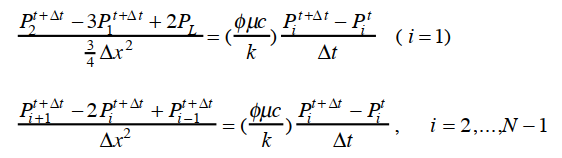

#### So we have two main parts,  first and final points. and a loop for midpoints matrix creation.

## **Implicit**($\left.\Delta x=0\ldotp 01\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.01;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/4*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/4*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=-3/4*alphavar*Ans(1,c-1)-2*PL;
B(L/dx)=-3/4*alphavar*Ans(L/dx,c-1)-2*PR;
for n=2:L/dx-1
    B(n)=-alphavar*Ans(n,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
Implicit1=Ans;

## **Implicit**($\left.\Delta x=0\ldotp 1\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.1;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/4*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/4*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=-3/4*alphavar*Ans(1,c-1)-2*PL;
B(L/dx)=-3/4*alphavar*Ans(L/dx,c-1)-2*PR;
for n=2:L/dx-1
    B(n)=-alphavar*Ans(n,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
Implicit2=Ans;

## **Implicit**($\left.\Delta x=0\ldotp 2\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.2;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/4*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/4*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=-3/4*alphavar*Ans(1,c-1)-2*PL;
B(L/dx)=-3/4*alphavar*Ans(L/dx,c-1)-2*PR;
for n=2:L/dx-1
    B(n)=-alphavar*Ans(n,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
Implicit3=Ans;

## for cranck-Nicholson, we use matrix form below:


$$\left\lbrack \begin{array}{ccc}
-\frac{3}{2}\alpha -3 & 1 & 0\\
1 & -2a-2 & 1\\
0 & 1 & -\frac{3}{2}a-3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
P_1 \\
P_{\mathrm{mid}} \\
P_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(-\frac{3}{2}a+3\right)P_1 -P_2 -4P_L \\
\left(-2a+2\right)P_i -P_{i+1} -P_i \\
\left(-\frac{3}{2}a+3\right)P_N -P_{N-1} -4P_R 
\end{array}\right\rbrack$$


## CN($\left.\Delta x=0\ldotp 01\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.01;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/2*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/2*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-2*alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=(-3/2*alphavar+3)*Ans(1,c-1)-4*PL-Ans(2,c-1);
B(L/dx)=(-3/2*alphavar+3)*Ans(L/dx,c-1)-Ans(L/dx-1,c-1)-4*PR;
for n=2:L/dx-1
    B(n)=(-2*alphavar+2)*Ans(n,c-1)-Ans(n+1,c-1)-Ans(n-1,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
CN1=Ans;

## CN($\left.\Delta x=0\ldotp 1\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.1;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/2*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/2*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-2*alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=(-3/2*alphavar+3)*Ans(1,c-1)-4*PL-Ans(2,c-1);
B(L/dx)=(-3/2*alphavar+3)*Ans(L/dx,c-1)-Ans(L/dx-1,c-1)-4*PR;
for n=2:L/dx-1
    B(n)=(-2*alphavar+2)*Ans(n,c-1)-Ans(n+1,c-1)-Ans(n-1,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
CN2=Ans;

## CN($\left.\Delta x=0\ldotp 2\;m\right)$

dt=1e-4;
tfinal=1;
dx=0.2;
alphavar=((dx^2)/(dt))*((mu*Ct*phi)/(k));
Coeff=zeros(L/dx);
Coeff(1,1)=-3/2*alphavar-3;
Coeff(1,2)=1;
Coeff(size(Coeff),size(Coeff))=-3/2*alphavar-3;
Coeff(size(Coeff),size(Coeff)-1)=1;
for f=2:size(Coeff)-1
    Coeff(f,f)=-2*alphavar-2;
    Coeff(f,f-1)=1;
    Coeff(f,f+1)=1;
end
Ans=zeros(L/dx,numel(0:dt:tfinal));
Ans(:,1)=Pi;%assign initial pressure to all points
B=zeros(L/dx,1);
c=1;
for j=0:dt:tfinal %time loop
    c=c+1;
B(1)=(-3/2*alphavar+3)*Ans(1,c-1)-4*PL-Ans(2,c-1);
B(L/dx)=(-3/2*alphavar+3)*Ans(L/dx,c-1)-Ans(L/dx-1,c-1)-4*PR;
for n=2:L/dx-1
    B(n)=(-2*alphavar+2)*Ans(n,c-1)-Ans(n+1,c-1)-Ans(n-1,c-1);
end
Ans(:,c)=(Coeff^-1)*B;
end
CN3=Ans;

## Comparing methods:

#### in all the methods we reached to simillar values but the main diffrence between these methods was their runtime which maked numerical methods better than analytical one. also between numerical methods explicit method had more runtime and it was because of its limitation in stability that forced us to use a smaller time step and increseing calcualtion steps.